# Clase 03_a >> Estructuras y sistemas

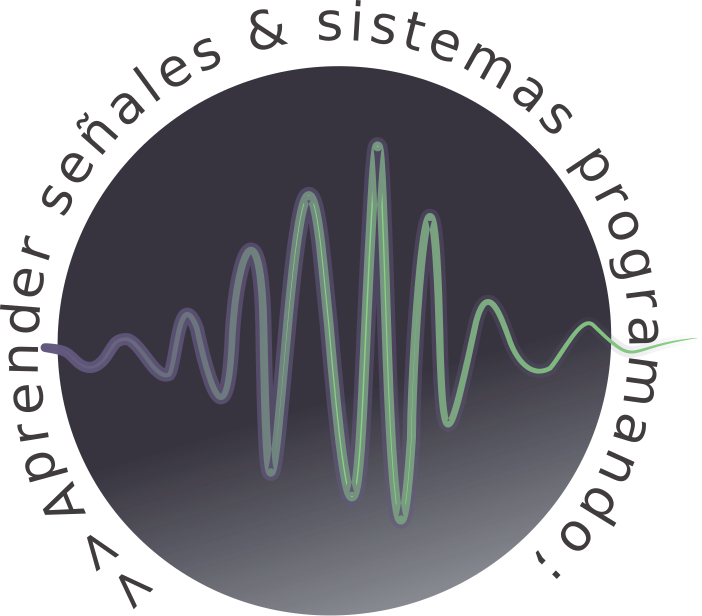

# Clasificación de sistemas

En este contexto, **un sistema puede considerarse como un proceso en el cual las señales de entrada son transformadas por el sistema o provocan que éste responda de alguna forma, lo que da como resultado otras señales de salida.** Por ejemplo, un sistema de alta fidelidad toma una señal de audio grabada y genera una reproducción de dicha señal. Si el sistema de alta fidelidad tiene controles de tono, podemos cambiar la calidad en el matiz de la señal reproducida.

Un sistema continuo es aquel en el cual las señales continuas de entrada son transformadas en señales continuas de salida:


$$x(t) \rightarrow y(t)$$


De la misma manera, un sistema discreto, es uno que transforma señales de entrada discretas en salidas de tiempo discreto:


$$x[n] \rightarrow y[n]$$


**Propiedades basicas de un sistema**

Vamos a repasar las 4 propiedades basicas de un sistema continuo, las mismas se aplican a sistemas discretos [Kamen, Edward W., 2008]:

- **Sistemas sin y con memoria: **Un sistema es** sin memoria, **si su salida para cada valor de la variable independiente en un tiempo dado depende solamente de la entrada en ese instante de tiempo.


$$S:y[n]=(2x[x]-x^2[n])^2$$
 

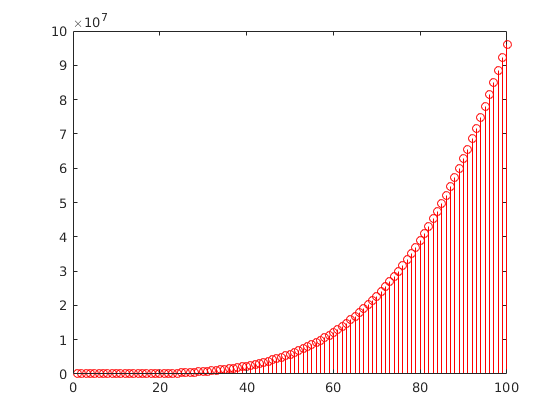

clear all

x = 1:100; 
y = (2*x-x.^2).^2;

clf
stem(y,'r');

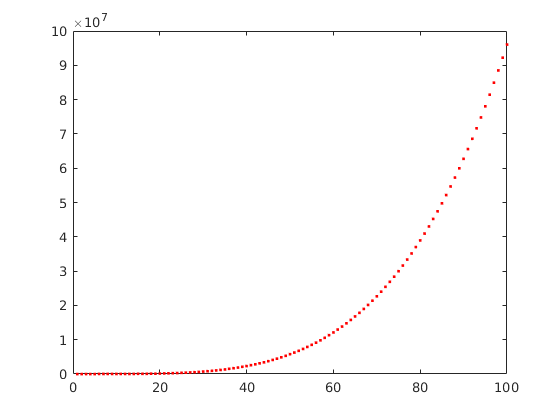

plot(y,'.r');  % Alternativa más legible

              Un sistema **con memoria **posee algun mecanismo en el sistema que almacena información sobre los valores de entrada en instantes anteriores (y/o futuro) al tiempo actual.


$$S:y[n]=y[n-1]+x[n]$$
 

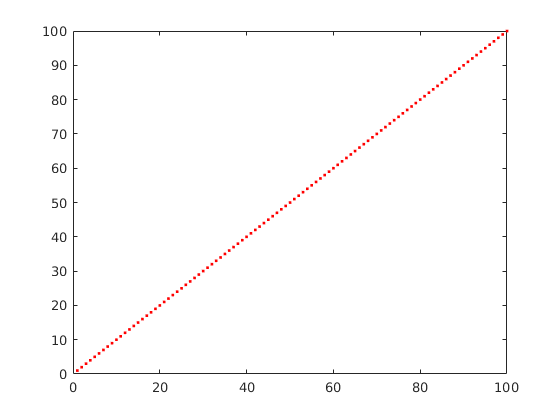

clear all

N = 100;
x = ones(1,N);  % secuencia

for n = 1:N
    y(n) = sum(x(1:n));
end
clf

plot(y,'.r') 

- **Invertibilidad y sistemas inversos: **Se dice que **un sistema es invertible** o inversible si distintas entradas producen distintas salidas. Si un sistema es inversible entonces existe el sistema inverso tal que cuando esta en cascada con el sistema original produce una salida w que es igual a la entrada. Un ejemplo de sistema inversible y su inversa es:


$$S_1:y[n]=\sum_{k=1}^{n}x[k]$$



$$S_2:w[n]=y[n]-y[n-1]$$


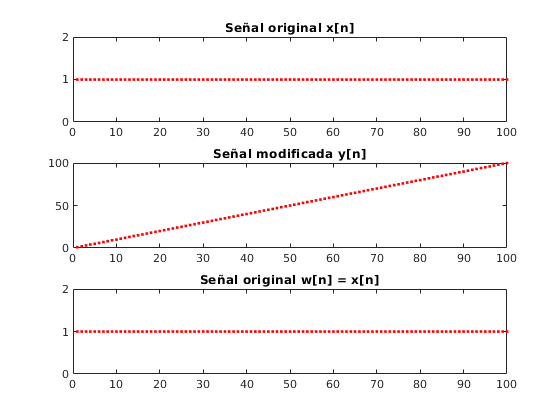

clear all

N = 100;
x = ones(1,N);  % secuencia original

for n = 1:N
    y(n) = sum(x(1:n));
end

% indice problematico (n=0)
y_0 = 0;
w(1) = y(1)-y_0;

for n = 2:N
    w(n) = y(n)-y(n-1);
end

clf
subplot(3,1,1)
plot(x,'.r'); title('Señal original x[n]');
subplot(3,1,2)
plot(y,'.r'); title('Señal modificada y[n]');
subplot(3,1,3)
plot(w,'.r'); title('Señal original w[n] = x[n]');

              Un ejemplo de **sistema no inversible** es:

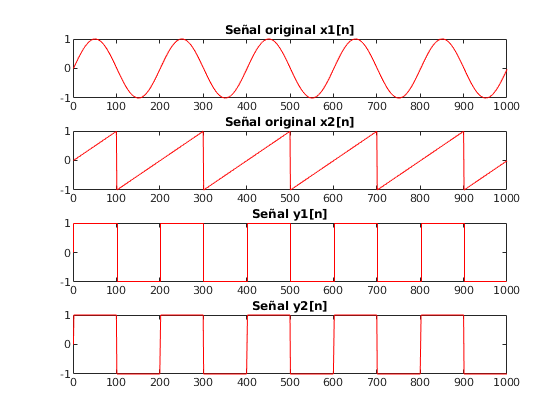

clear all

T = 5*(1/50);
Fs = 10000;
dt = 1/Fs;
t = 0:dt:T-dt;

x1 = sin(2*pi*50*t);
x2 = sawtooth(2*pi*50*t+pi);  % diente de sierra
y1 = sign(x1);  % funcion signo
y2 = sign(x2);

clf
subplot(4,1,1)
plot(x1,'r'); title('Señal original x1[n]');
subplot(4,1,2)
plot(x2,'r'); title('Señal original x2[n]');
subplot(4,1,3)
stairs(y1,'r'); title('Señal y1[n]');
subplot(4,1,4)
plot(y2,'r'); title('Señal y2[n]');

- **Causalidad:** Un sistema es **causal **si su salida en cualquier instante de tiempo depende sólo de los valores de entrada en el momento presente y en el pasado. También se los llama **no anticipativo. Todos los sistemas sin memoria son causales ya que la salida responde sólo a valores presentes de la entrada y/o salida. **Un ejemplo de sistema **causal.**


$$S_1:y[n]=\sum_{k=-\infty}^{n}x[k]$$



$$S_2:y[n]=x[n]cos(n+1) \qquad \text{¿Es causal?}
$$


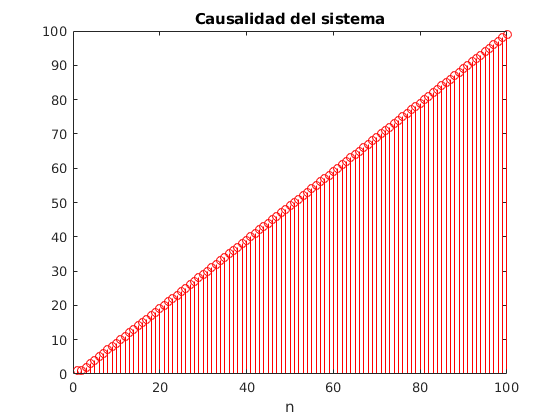

clear all

N = 100;
x = ones(1,N);  % secuencia
x_0 = 1;
y(1)= x_0;

for n = 2:N
    y(n) = sum(x(2:n));
end

clf
stem(y,'r'); title('Causalidad del sistema'); xlabel('n')

            Un sistema **no** **causal.**


$$S:y[n]=x[n+1]$$


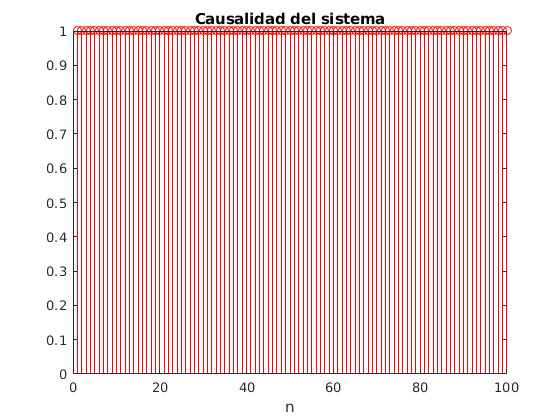

clear all

N = 100;
x = ones(1,N);  % secuencia

x(101) = 1;

for n = 1:N
    y(n) = x(n+1);
end

clf
stem(y,'r'); title('Causalidad del sistema'); xlabel('n')

- **Estabilidad: **Sabemos que un procedimiento para determinar si **un sistema es estable**, si este es LTI. es comprobar que la respuesta impulsiva tiene suma acotada, sin embargo para sistemas no LTI debemos aplicar la definición general (cualquier entrada acotada produce una salida acotada) [Olivas, Emilio Soria, 2003]. En definitiva, un sistema es estable cuando perturbaciones pequeñas de la entrada conducen a respuestas que no divergen. Ejemplo de un **sistema inestable**.


$$S:y[n]=tx[n]$$


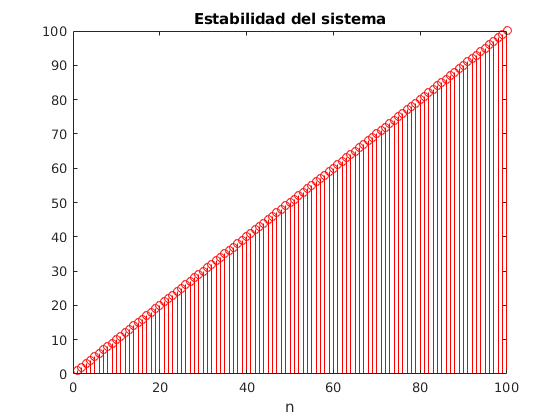

clear all

N = 100;
x = [1 ones(1,N-1)];  % secuencia para estudiar la ESTABILIDAD.

for n = 1:N
    y(n) = n*x(n);
end

clf
stem(y,'r'); title('Estabilidad del sistema'); xlabel('n')

              Un sistema **estable**.


$$S:y[n]=e^{x[n]}$$


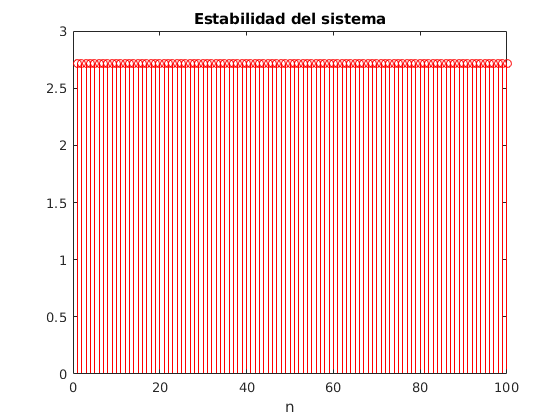

clear all

N = 100;
x = [1 ones(1,N-1)];  % secuencia para estudiar la ESTABILIDAD.

for n = 1:N
    y(n) = exp(x(n));
end

clf
stem(y,'r'); title('Estabilidad del sistema'); xlabel('n')

- **Invariancia en el tiempo: **Un sistema es **invariante en el tiempo** si el comportamiento y características del mismo están fijos en el tiempo. Un sistema es invariante con el tiempo si un desplazamiento temporal en la entrada ocasiona un despazamiento temporal en la salida.


$$S_1:y[n]=sen[x[n]] \qquad \text{Verificar que es invariante en el tiempo.}$$



$$S_2:y[n]=nx[n] \qquad \text{Verificar que es variante en el tiempo.}$$


- **Linealidad: Un sistema lineal**, tanto en tiempo continuo como discreto posee la importante propiedad de superposición es decir si una entrada es la suma ponderada de varias señales la salida es la superposición de las respuestas del sistema a cada una de estas señales.


$$ax_1[n] \rightarrow ay_1[n] \\
bx_2[n] \rightarrow by_2[n] \\
\text{Entonces: } x_3=ax_1[n]+bx_2[n]\rightarrow y_3=ay_1[n]+by_2[n] \\$$


             En un sistema lineal, si la entrada es nula, la salida también debe serlo. Analicemos la linealidad del siguiente sistema:


$$S_1:y[n]=tx[n]$$



$$S_2:y[n]=x^2[n]$$



$$S_3:y[n]=2x[n]+3$$


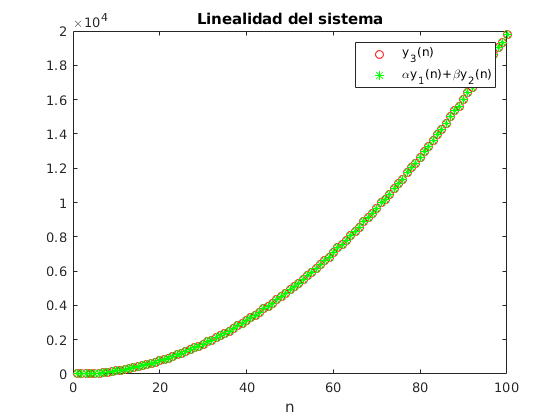

clear all

N = 100;
alfa = 2; beta = 0.5;
    
x1 = 0:N-1;                         % secuencia arbitraria n°1, para el estudio de la LINEALIDAD.
x2 = sin(2*pi*0.3*(1:N));           % secuencia arbitraria n°2, para el estudio de la LINEALIDAD.
x3 = alfa*x1 + beta*x2;             % combinacion lineas de las secuencias n°1 y n°2, para el estudio de la LINEALIDAD.

for n = 1:N
    y1(n) = n*x1(n);
    y2(n) = n*x2(n);
    y3(n) = n*x3(n);
end
clf
plot(y3,'ro')
hold on
plot(alfa*y1+beta*y2,'g*');title('Linealidad del sistema');xlabel('n');legend('y_3(n)','\alphay_1(n)+\betay_2(n)')

Veamos un ejemplo para verificar la **linealidad**, la **estabilidad** e **invarianza temporal** de un sistema discreto: 


$$y[n] = x[n]-2x[n-1]-y[n-2]$$


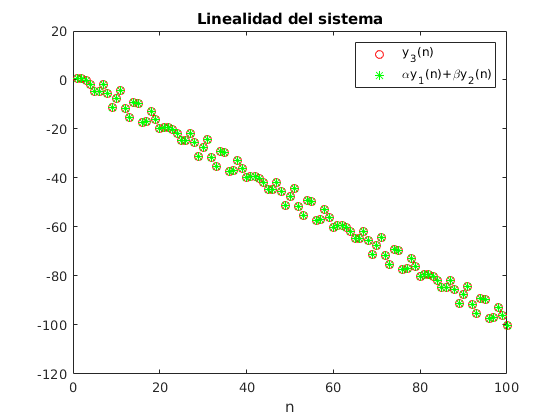

% Importante: se considera el primer elemento como n = 1 y no n = 0

    clear all
    close all

% Generamos 5 secuencia para estudiar el sistema
    N = 100;
    alfa = 2; beta = 0.5;
    
    x1 = 0:N-1;                         % secuencia arbitraria n°1, para el estudio de la LINEALIDAD.
    x2 = sin(2*pi*0.3*(1:N));           % secuencia arbitraria n°2, para el estudio de la LINEALIDAD.
    x3 = alfa*x1 + beta*x2;             % combinacion lineas de las secuencias n°1 y n°2, para el estudio de la LINEALIDAD.
    x4 = [1 zeros(1,N-1)];              % secuencia para estudiar la ESTABILIDAD.
    x5 = [zeros(1,5) x1(1:N-5)];        % secuencia para estudiar la INVARIANZA TEMPORAL, retardando 5 muestras.

% Consideramos las siguientes condiciones iniciales n = 1 --> x [n-1] = 0 ; y[n-2] = 0.5 // n = 2 --> y[n-2] = 2
    y_1 = 0; y0 = 0; x0 = 0;
    
% Ahora, debemos calcular las salidas para las entradas anteriores y1[n],y2[n], y3[n], y4[n], por ultimo y5[n]   

% Primero, determinamos fuera del bucle la salida para índices problemáticos n = 1 y n = 2

% Para n = 1
    n = 1;
    y1(n) = x1(1)-2*x0-y_1;
    y2(n) = x2(1)-2*x0-y_1;
    y3(n) = x3(1)-2*x0-y_1;
    y4(n) = x4(1)-2*x0-y_1;
    y5(n) = x5(1)-2*x0-y_1;
    
% Para n = 2
    n = 2;
    y1(n) = x1(2)-2*x1(2-1)-y0;
    y2(n) = x2(2)-2*x2(2-1)-y0;
    y3(n) = x3(2)-2*x3(2-1)-y0;
    y4(n) = x4(2)-2*x4(2-1)-y0;
    y5(n) = x5(2)-2*x5(2-1)-y0;
    
% Realizamos los cálculos para n > 2
for n = 3:N
    y1(n) = x1(n)-2*x1(n-1)-y1(n-2);
    y2(n) = x2(n)-2*x2(n-1)-y2(n-2);
    y3(n) = x3(n)-2*x3(n-1)-y3(n-2);
    y4(n) = x4(n)-2*x4(n-1)-y4(n-2);
    y5(n) = x5(n)-2*x5(n-1)-y5(n-2);
end

% Dibujamos las salidas
    plot(y3,'ro')
    hold on
    plot(alfa*y1+beta*y2,'g*');
    title('Linealidad del sistema')
    xlabel('n')
    legend('y_3(n)','\alphay_1(n)+\betay_2(n)')

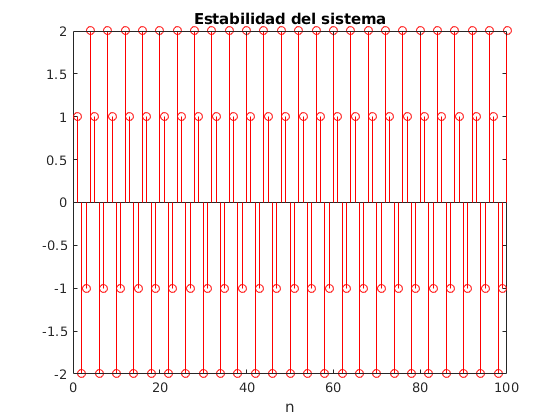

    
    clf
    stem(y4,'r')
    title('Estabilidad del sistema')
    xlabel('n')

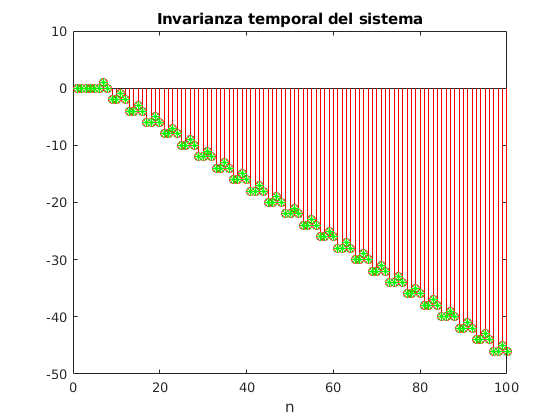

  
    clf
    stem(y5,'ro')
    title('Invarianza temporal del sistema')
    xlabel('n')
    hold on
    plot([zeros(1,5) y1(1:N-5)],'g*');
    xlabel('n')

## Ejercicios de la guía n°2 (script_03_01)

Resolver el ejercicio n°2, 3,  5, 6, 7 y 8 con un script en MATLAB.

Ejemplo, en el ejercicio n°5, determine si el sistema definido por la transformación T es lineal.


$$y[n]=t\lbrace x[n] \rbrace = \frac{1}{3} \lbrace x[n+1] + x[n] + x[n-1] \rbrace$$


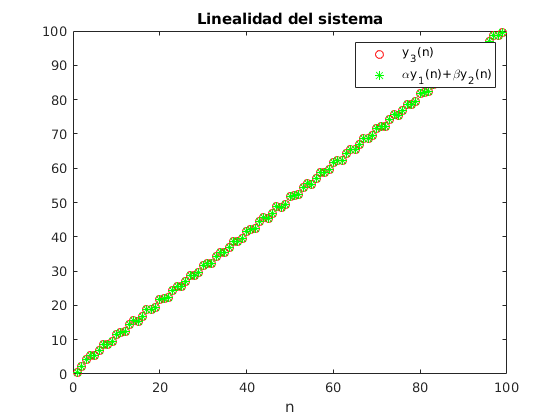

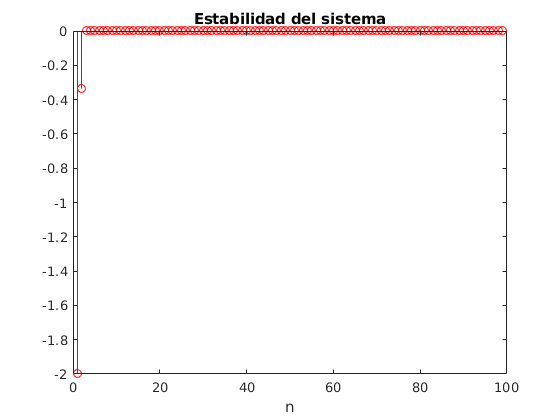

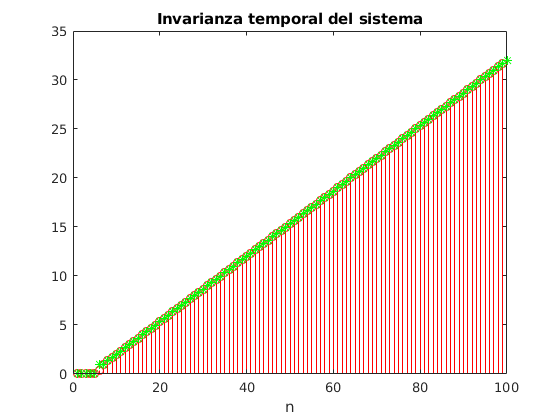

script_03_01()

# Estructuras de control (o sentencias) (II)

Retomando lo visto, veamos algunos ejemplos para repazar :

## **Sentencia condicional finita**

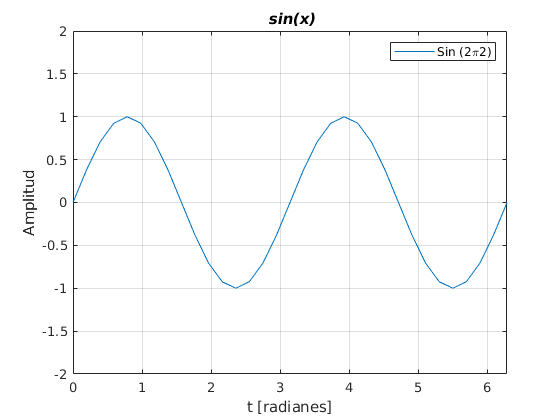

ejemplo_03_01(2) % Script para plotear la señal senoidal de frecuencia definida por el argumento de la función.

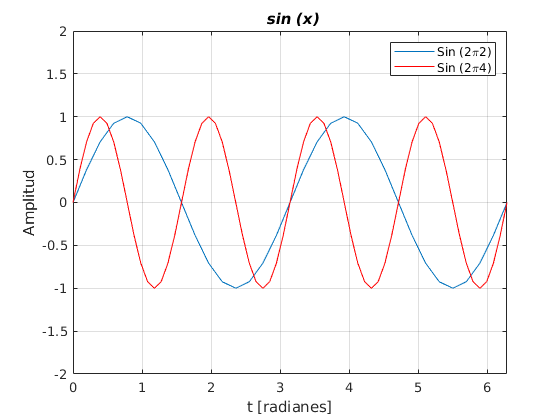

ejemplo_03_01(2,4)

% ejemplo_03_01(2,4,8)

## **Sentencia condicional por casos**

ejemplo_03_02()

Ponderacion A


## Sentencia condicional infinita

 ejemplo_03_03 % Script para calcular el logaritmo natural de un numero ingresado

Debe ingresar un numero positivo 
Este programa terminara


## Sentencia bucle

Veamos un ejemplo de rendimiento de estas estructuras. Es importante evitar en lo posible el uso de bucles en MATLAB, ya que consumen mucho tiempo, pudiéndose en muchos casos realizar las mismas operaciones de una forma más eficiente y compacta. Los siguientes ejemplos calculan logaritmos de números desde 1 a 10000. Se hará de diferentes maneras para comparar. Se utilizan los comandos **clock **(que devuelve la hora actual) y **etime **(que devuelve el tiempo en segundos que ha transcurrido entre dos instantes) para calcular el tiempo consumido en las operaciones:

clear all;

t1 = clock; for i = 1:10000, a(i) = log(i); end; e1 = etime(clock,t1);

t1 = clock; ind = 1:10000; for i = ind, a(i) = log(i); end; e2 = etime(clock,t1);

t1 = clock; a = zeros(1,10000); ind = [1:10000]; for i = ind, a(i) = log(i); end; e3 = etime (clock,t1);

t1 = clock; ind = 1:10000; a = log(ind); e4 = etime(clock, t1);

t1 = clock; ind = 1:10000; a = zeros(1,10000); a = log(ind); e5 = etime(clock,t1);

e1

e1 = 0.0065

e2

e2 = 0.0028

e3

e3 = 0.0040

e4

e4 = 0.0025

e5

e5 = 3.4700e-04

Las causas de la disminución importante de tiempos es que en los primeros métodos, MATLAB tiene que recalcular la dimensión del vector cada pasada por el bucle (importancia de las inicializaciones), y además usar bucles for, que como se ha indicado, consumen mucho tiempo. Esto por supuesto no quiere decir que no deban usarse, pues habrá ocasiones en que no haya más remedio, pero siempre que haya una forma alternativa de hacerlo, esta será preferible al uso de bucles [Manuel Vargas, 2004].

## ¿Por qué es tan importante la vectorización?

Dentro de la vectorización de codigo en MATLAB la función **find** tiene dos caracteristicas muy importantes, para esta tarea:

- Devuelve indices de valores distintos a cero.

- Simplifica codigo y ayuda a evitar bucles for.

clc
clear all

x = rand(1,100)

x =     0.8147    0.9058    0.1270    0.9134    0.6324    0.0975    0.2785    0.5469    0.9575    0.9649    0.1576    0.9706    0.9572    0.4854    0.8003    0.1419    0.4218    0.9157    0.7922    0.9595    0.6557    0.0357    0.8491    0.9340    0.6787    0.7577    0.7431    0.3922    0.6555    0.1712    0.7060    0.0318    0.2769    0.0462    0.0971    0.8235    0.6948    0.3171    0.9502    0.0344    0.4387    0.3816    0.7655    0.7952    0.1869    0.4898    0.4456    0.6463    0.7094    0.7547


ind = find(x > 0.4 & x < 0.5)

ind =     14    17    41    46    47    56    80    98


Veamos un ejemplo, donde queda claro la ventaja de aplicar **find**:

x = sin(linspace(0,10*pi,10000))

x =          0    0.0031    0.0063    0.0094    0.0126    0.0157    0.0189    0.0220    0.0251    0.0283    0.0314    0.0346    0.0377    0.0408    0.0440    0.0471    0.0502    0.0534    0.0565    0.0597    0.0628    0.0659    0.0691    0.0722    0.0753    0.0785    0.0816    0.0847    0.0879    0.0910    0.0941    0.0972    0.1004    0.1035    0.1066    0.1097    0.1129    0.1160    0.1191    0.1222    0.1253    0.1285    0.1316    0.1347    0.1378    0.1409    0.1440    0.1471    0.1502    0.1533


t1 = clock;
count = 0;
for n = 1:length(x)
    if x(n) > 0
        count = count + 1;
    end
end
e1 = etime(clock,t1)

e1 = 0.0867

count

count = 4999


t1 = clock;
count = length(find(x>0));
e2 = etime(clock,t1)

e2 = 0.0114

count

count = 4999

## Sentencia break, continue, return

La sentencia **break**  termina la ejecución de un bucle **for** o **while**. Las declaraciones que continuan en el hilo (thread) después de la instrucción **break** no se ejecutaran. En bucles anidados, **break **sale sólo por el bucle en el que se produce.

En éste ejemplo, se suma una secuencia de números al azar hasta que el siguiente número aleatorio es superior a un límite superior. A continuación, se sale del bucle utilizando una instrucción** break.**

limit = 0.8;
s = 0;

while 1
    tmp = rand
    if tmp > limit
        break
    end
    s = s + tmp
end

tmp = 0.1622

s = 0.1622

tmp = 0.7943

s = 0.9565

tmp = 0.3112

s = 1.2677

tmp = 0.5285

s = 1.7962

tmp = 0.1656

s = 1.9619

tmp = 0.6020

s = 2.5638

tmp = 0.2630

s = 2.8268

tmp = 0.6541

s = 3.4809

tmp = 0.6892

s = 4.1701

tmp = 0.7482

s = 4.9183

tmp = 0.4505

s = 5.3688

tmp = 0.0838

s = 5.4526

tmp = 0.2290

s = 5.6816

tmp = 0.9133

**continue**, pasa el control a la siguiente iteración de un bucle **for** o **while** . Salta las declaraciones restantes en el cuerpo del bucle para la iteración actual y continúa la ejecución de la siguiente iteración.

Como en el caso de **break**, **continue** sólo se aplica al cuerpo del bucle donde se llama. Ademan en bucles anidados,** continue** omite declaraciones restantes sólo en el cuerpo del bucle en el que se produce.

A continuacion se muestra los múltiplos de 7 entre 1 y 50. Si un número no es divisible por 7, se utiliza **continue** para omitir la instrucción **disp** y pasar el control a la siguiente iteración del bucle **for** .

for n = 1:50
    if mod(n,7)
        continue
    end
    disp(['Divisible por 7: ' num2str(n)])
end

Divisible por 7: 7
Divisible por 7: 14
Divisible por 7: 21
Divisible por 7: 28
Divisible por 7: 35
Divisible por 7: 42
Divisible por 7: 49



limit = 0.8;
s = 0;

**return ** fuerza el control a la función de invocación antes de que llegue el final de la función. La función de invocar es la función que llama al script o función que contiene la llamada a **return**. Si llama a la función o la secuencia de comandos que contiene **return** directamente, no hay ninguna función de invocación y MATLAB devuelve el control al prompt de comando.

help return

return - Return control to invoking function

    This MATLAB function forces MATLAB to return control to the invoking function
    before it reaches the end of the function.

    return

    See also <a href="https://www.mathworks.com/help/releases/R2018b/matlab/ref/break.html">break</a>, <a href="https://www.mathworks.com/help/releases/R2018b/matlab/ref/continue.html">continue</a>, <a href="https://www.mathworks.com/help/releases/R2018b/matlab/ref/disp.html">disp</a>, <a href="https://www.mathworks.com/help/releases/R2018b/matlab/ref/end.html">end</a>, <a href="https://www.mathworks.com/help/releases/R2018b/matlab/ref/error.html">error</a>, <a href="https://www.mathworks.com/help/releases/R2018b/matlab/ref/for.html">for</a>, <a href="https://www.mathworks.com/help/releases/R2018b/matlab/ref/if.html">if</a>, <a href="https://www.mathworks.com/help/releases/R2018b/matlab/ref/keyboard.html">keyboard</a>, <a href="https://www.mathworks.com/help/releases/R2018b/matlab/ref/switch.html">swi

**Consejos:**

- La instrucción **break** sale de un bucle **for** o **while** completamente. Para omitir el resto de las instrucciones en el bucle y comenzar la siguiente repetición, utilice una instrucción **continue**.

- **break** no está definida fuera de un bucle **for** o **while** . Para salir de una función, utilice **return**.

- La declaración **continue** salta el resto de las instrucciones de un bucle **for** o **while** y comienza la siguiente iteración. Para salir del bucle totalmente, utilice una instrucción **break** .

- **continue **no está definida fuera de un bucle **for** o **while**. Para salir de una función, utilice **return**.

# Manejo de errores

La sentencia utilizada para tal fin es **try/catch**. Este enfoque permite reemplazar el comportamiento predeterminado de un error para un conjunto de declaraciones del programa. Si cualquier declaración en un bloque **try** genera un error, el thread del programa va inmediatamente al bloque **catch**, que contiene las declaraciones de su error. La estructura es la siguiente:


$$\textbf{try} \\ \qquad  \text{sentencia;}
\\ \textbf{catch} \text{ excepción}\\
\qquad  \text{sentencia;}\\
\textbf{end}$$


**exception** (excepción) es un objeto **MException** que le permite identificar el error. El bloque **catch** asigna el objeto de la excepción actual a la variable de **exception**.

Un ejemplo del uso de **try/catch** para manejar diferentes tipos de errores de diferentes maneras.

- Si no está definida la función **promedio**, emitir una advertencia en lugar de un error y asignar la salida un valor de **NaN **(con el objetivo de continuar el siguiente thread y no colgar el script).

- Si **promedio.m** existe, pero es un script en lugar de una función (que no tiene el encabezado `function`), hacer una advertencia en lugar de un error, ejecute el script y asignar la salida un valor de 0.

- Si MATLAB arroja un error por cualquier otro motivo, volver a iniciar la excepción.

try
%     a = promedio([5,7,8]) 
%     a = promedio(5,6) 
%     a = promedio()
    a = promedio2([5,7,8])
    
catch ME
    switch ME.identifier
        case 'MATLAB:UndefinedFunction'
            warning('La función no se encuentra en el directorio. Asignando NaN a la salida.');
            a = NaN;
        case 'MATLAB:scriptNotAFunction'
            warning(['Intentando ejecutar un script como una funcion. Asignando 0 a la salida.']);
            a = 0;
        otherwise
            rethrow(ME)
    end
end

**Consejos:**

- No se pueden utilizar varios bloques `catch` dentro de un bloque `try` , pero puede anidar los bloques `try/catch.`

- A diferencia de otros lenguajes, MATLAB no permite el uso de un bloque `finally` de instrucciones `try/catch` .

Hay otras estructuras un poco más avanzadas como es el caso de **try, catch, **con el objetivo de ejecutar código después de que su programa encuentra un error**.** Buscar más infomación en:

help try

try - Execute statements and catch resulting errors

    This MATLAB function executes the statements in the try block and catches
    resulting errors in the catch block.

    try statements, catch statements end

    See also <a href="https://www.mathworks.com/help/releases/R2018b/matlab/ref/mexception-class.html">MException</a>, <a href="https://www.mathworks.com/help/releases/R2018b/matlab/ref/assert.html">assert</a>, <a href="https://www.mathworks.com/help/releases/R2018b/matlab/ref/error.html">error</a>

    Reference page for try



# Estructura de datos avanzada

No todo son aplicaciones sencillas donde escalares, vectores y matrices bastan. Tampoco es cierto que los datos más complejo suelen ser los argumentos que pasamos a las funciones. Un programa puede requerir variables que contengan tipos de gran complejidad, normalmente obligados por el propio algoritmo. Supongamos que trabajamos con una población de datos especialmente compleja, algo usual en una base de datos. Pongamos como ejemplo una descripción de todos los trabajadores de una empresa. Esto es un ejemplo, seguramente no utilizaremos un lenguaje de programación orientado a cálculo numérico para resolver un problema como este pero otras aplicaciones como los algoritmos genéticos pueden requerir tipos derivados especialemnte complejos [Nogueras, Guillem, 2007].

La pregunta más común es: ¿Por qué recurrir a estructuras más avanzadas si tengo matrices o arrays?, para responder vamos a listar algunas ventajas y desventajas de estos dos estructuras :

Las matrices son:

- Estructuras de n dimensiones.

- Todos los elementos que lo componen deben tener el mismo tipo (char, bool, int, double, etc).

- Estructuras muy eficientes para calculo.

- Las matrices pueden ser **sparse **(reducir tamaño en memoria, de matrices con ceros)

a = zeros(100); a(1,3) = 10; a(21,5) = pi; b = sparse(a);

Tenemos dos alternativas a las estructuras ya vistas:

- **Cell array**: es como un array, pero los elementos no deben ser necesariamente del mismo tipo.  A diferencia de las estructuras de datos no tendremos que asignar un nombre a cada una de las celdas porque ya se les asignará un grupo de índices.

- **Structs: **es una estructura del tipo arbol, que puede tener sus propios nombres de variables y valores dentro de si misma (parecido a como se trabaja con objetos OOP, object oriented programming).

## **Cell a****rray**

Las celdas son matrices o hiper-matrices de variables. No debemos confundirlas con las matrices usuales que son estructuras de argumentos del mismo tipo. Una celda puede contener matrices, cadenas de texto y argumentos lógicos a la vez siempre que estén en celdas separadas. A diferencia de las estructuras de datos no tendremos que asignar un nombre a cada una de las celdas porque ya se les asignará un grupo de índices.

Inicialización y indexación:

clc
clear all

a = cell(3,10)

a = 3×10 cell array
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


b = {'Señales y sistemas',[15 02 2017]}

b = 1×2 cell array
    {'Señales y sistemas'}    {1×3 double}


b{1,1}

ans = 'Señales y sistemas'

c = {'Luis',20;'Maria', 32;'Jose', 18}

c = 3×2 cell array
    {'Luis' }    {[20]}
    {'Maria'}    {[32]}
    {'Jose' }    {[18]}


c{1:end,1}

ans = 'Luis'

ans = 'Maria'

ans = 'Jose'

c{2,:}

ans = 'Maria'

ans = 32

**Import****ante:** las celdas pueden almacenar cualquier tipo de argumento, incluso funciones. **Es más fácil y rápido escribirlos utilizando llaves**.Como en el caso de las matrices convencionales podremos ampliar las celdas con sólo llenar una que no tenga ningún argumento asignado; las celdas sobrantes quedan vacías.

## Structs

Inicialización de estructuras:

campo1 = 'materia';  valor1 = 'Señales y sistemas';
campo2 = 'fecha';  valor2 = datetime('today');
campo3 = 'docentes';  valor3 = ['Miryam','Antonio','Maxi'];
campo4 = 'examenesNotas';  valor4 = [8.00, 4.00, 0, 0];

s = struct(campo1,valor1,campo2,valor2,campo3,valor3,campo4,valor4);
clear campo1 campo2 campo3 campo4 valor1 valor2 valor3 valor4

Alternativa para añadir campos a la estructura de forma más compacta:

U.materia = 'Señales y sistemas';
U.fecha = datetime('today');
U.docentes = ['Miryam','Antonio','Maxi'];
U.examenes = ['Primer parcial', 'Segundo parcial', 'Final', 'Promedio'];
U.examenesNotas = [8.00, 4.00, 0, 0];

## Table

No es una estructura por si sola, se desprende de un caso particular de **struct**:

Apellido = {'Perez';'Gonzales';'Fernandez';'Botara';'Brown'};
Edad = [38;43;38;40;49];
Peso = [71;69;64;67;64];
Altura = [176;163;151;173;199];

T = table(Edad,Peso,Altura,'RowNames',Apellido)

T = 5×3 table
                 Edad    Peso    Altura
                 ____    ____    ______

    Perez         38      71      176  
    Gonzales      43      69      163  
    Fernandez     38      64      151  
    Botara        40      67      173  
    Brown         49      64      199  


# Uicontrol

## Structura, introducción al diseño de software  "uiControl" (script_03_02)

En este script vamos a trabajar más cerca a una aplicación final. Para lo cual vamos a definir dos partes del software:

- Back-end: métodos para la manipulación de los datos.

- Front-end: métodos para la interacción del usuario, ingreso de datos y consulta.

En este primer script, vamos a realizar una función que define la estructura en función de los campos que el usuario ingresa. Para facilitar la tarea, a continuación se presenta la estructura básica, complete con los campos que falta.

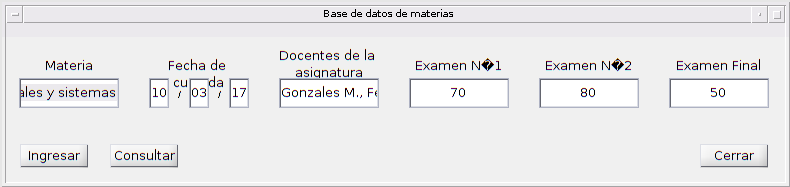

script_03_02()

Este ejemplo es muy importante ya que presenta el primer acercamiento a la programación orientada a objetos, la estructura de este script esta pensada para ser reutilizada y permitir su expansión o modificacion sin necesidad de modificar todo el código.

## Base de datos de materiales acústicos (script_03_03)

Con el uso del script8 y script8_main, diseñe un programa para ingresar materiales acústicos a una base de datos, la cual se almacene en .csv (comma separated values) y pueda consultarse.

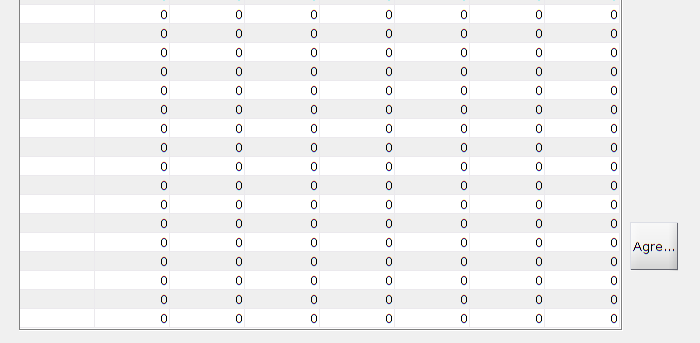

script_03_03()

Base de datos de materiales de consulta [Link](http://cds.cern.ch/record/1251519/files/978-3-540-48830-9_BookBackMatter.pdf).

# Referencias

- Vargas, Manuel; Berenguel, Manuel. ***Introducción a Matlab y su aplicación al Análisis y Control de Sistemas***. 2004

- Yossi Farjoun. *RES.18-002**** Introduction to MATLAB****. *Massachusetts Institute of Technology: MIT OpenCourseWare, [https://ocw.mit.edu](https://ocw.mit.edu/resources/res-18-002-introduction-to-matlab-spring-2008). License: [Creative Commons BY-NC-SA](https://creativecommons.org/licenses/by-nc-sa/4.0/). Spring 2008

- Kamen, Edward W., and Bonnie S. Heck. ***Fundamentos de señales y sistemas usando la Web y Matlab***. Pearson Prentice-Hall, 2008

- Olivas, Emilio Soria. ***Tratamiento digital de señales: problemas y ejercicios resueltos***. Pearson Educación, 2003

- Nogueras, Guillem. ***Introducción informal a Matlab y Octave.*** Universidad Politecnica de Madrid, 2007